%globemodel
wgs84 = wgs84Ellipsoid("m");

% lat long of location
lat=34.24063

lat = 34.2406

long=-119.05522

long = -119.0552

exgs=maidenheadex(lat,long)

digit7 = 3

char7 = '3'

digit8 = 7

char8 = '7'

exmh = 'DM04LF37'

exgs = 'DM04LF37'

subdivide=[10,15] %vertical subdvisions and horizontal subdivsions

subdivide =     10    15



%2m 30s by 5 min square 8 charachter extended grid square around given lat
%long (green)
gridlats=linspace(lat-mod(lat,1/240),lat-mod(lat,1/240)+dms2degrees([0 0 15]),subdivide(1))

gridlats =    34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417


gridlons=linspace(long-mod(long,1/120), long-mod(long,1/120)+dms2degrees([0 0 30]),subdivide(2))

gridlons =  -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500


[X,Y]=meshgrid(gridlats,gridlons)

X =    34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2412   34.2417
   34.2375   34.2380   34.2384   34.2389   34.2394   34.2398   34.2403   34.2407   34.2

Y =  -119.0583 -119.0583 -119.0583 -119.0583 -119.0583 -119.0583 -119.0583 -119.0583 -119.0583 -119.0583
 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577 -119.0577
 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571 -119.0571
 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565 -119.0565
 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560 -119.0560
 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554 -119.0554
 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548 -119.0548
 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542 -119.0542
 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536 -119.0536
 -119.0530 -119.0530 -119.0530 -119.0530 -119.0530 -119.0530 -119.0530 -119.0530 -119.0

%subgriddims=

vdis=distance(X(1,1),Y(1,1),X(1,2),Y(1,2),wgs84) %distance in meters

vdis = 51.3549

hdis=distance(X(1,1),Y(1,1),X(2,1),Y(2,1),wgs84) %distance in meters

hdis = 54.8374

sqrt(vdis*hdis)

ans = 53.0676

lats=reshape(X,1,[])

lats =    34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2375   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2380   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2384   34.2389   34.2389   34.2389   34.2389   34.2389


lons=reshape(Y,1,[])

lons =  -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500 -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500 -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500 -119.0583 -119.0577 -119.0571 -119.0565 -119.0560


g=geoscatter(lats,lons,"filled","white")

g =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
       LatitudeData: [34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 … ] (1×150 double)
      LongitudeData: [-119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500 -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 … ] (1×150 double)
              ZData: [1×0 double]
           SizeData: 36
              CData: [1 1 1]

  Show 

g.SizeData=10

g =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
       LatitudeData: [34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2375 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 34.2380 … ] (1×150 double)
      LongitudeData: [-119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 -119.0548 -119.0542 -119.0536 -119.0530 -119.0524 -119.0518 -119.0512 -119.0506 -119.0500 -119.0583 -119.0577 -119.0571 -119.0565 -119.0560 -119.0554 … ] (1×150 double)
              ZData: [1×0 double]
           SizeData: 10
              CData: [1 1 1]

  Show 

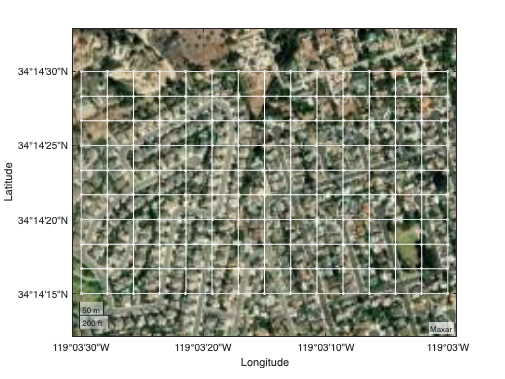

geobasemap satellite
hold on
for i=1:subdivide(2)
    geoplot([lats(i) lats((subdivide(1)-1)*subdivide(2)+i)],[lons(i) lons((subdivide(1)-1)*subdivide(2)+i)],"white")
end
for i=1:subdivide(2):subdivide(1)*subdivide(2)
    geoplot([lats(i) lats(i+subdivide(2)-1)],[lons(i) lons(i+subdivide(2)-1)],"white")
end
hold off